Companion software for "Volker Ziemann, *Physics and Finance, Springer, 2021*" ([https://link.springer.com/book/10.1007/978-3-030-63643-2](https://link.springer.com/book/10.1007/978-3-030-63643-2))

# F-test (Section 7.7)

Volker Ziemann, 211125, CC-BY-SA-4.0

In this example we plot the f-distribution $\Psi_{n,m}(f)$, defined in Equation 7.42, for the distribution of the test-statistics f, which is defined in Equation 7.38 and quantifies by how much the $\chi^2$ of a least-squares fit increases, if $n$ fit-parameters are excluded from the fit. The parameter $m$ is given by the number of data points $N$ minus the number of fit-parameters of the original fit with many fit-parameters.

The two sliders are used to select `n` and `m`, where the first one `n` the number of fit-parameters we want to omit from our fit and `m` is roughly given by the number of data points $N$, if that is very large. Then we define the range of f we wish to plot and use MATLAB's built-in function pdf() to produce the data, which we subsequently plot

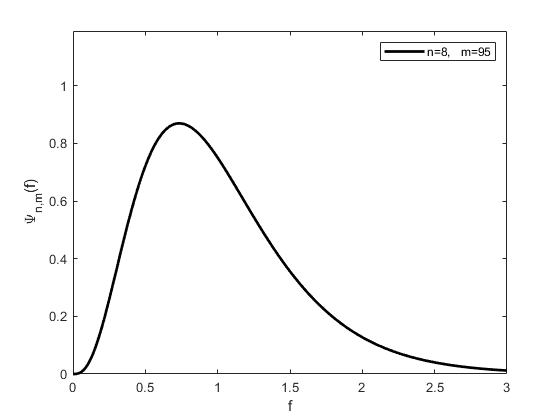

n=8;  % Slider to select n = q-p
m=95;  % Slider to select m = N-q 
f=0:0.01:3;
psi=pdf('F',f,n,m);
plot(f,psi,'k','LineWidth',2)
ylim([0 1.19])
xlabel('f')
ylabel('\Psi_{n,m}(f)')
legend(['n=',num2str(n),',   m=',num2str(m)])